% Allison Cairns
% PH. 495: Materials Physics
% Homework #1 - Julian: Table 1.2
% Revision 1.6 - May 2, 2020

clc;clear all; close all;
% Hammond's Data - Table 1.2

T = [188:10:328]; % [K: Kelvin]
a = [5.61365, 5.61652, 5.61902, 5.62233, 5.62423, 5.62731, 5.63022, 5.63642, 5.63913, 5.64140, 5.64554, 5.64492, 5.64854, 5.65101, 5.65360]; % [A: Angstrom]
c = [4.69524, 4.69680, 4.69698, 4.69706, 4.69821, 4.69882, 4.69916, 4.69939, 4.70015, 4.70053, 4.70081, 4.70204,4.70249, 4.70253, 4.70312]; % [A: Angstrom]

a2 = log(a);
c2 = log(c);

% Saved data from Matlab
% % linear fit - for lattice parameter a
% cubic fit a
cresids = [-2.58394554153440*10^-05, 5.91722133567174*10^-05, 2.37576187391841*10^-05, 8.88374755869670*10^-05, -0.000129552012103851, -0.000159861979912357, -0.000231252096494217, 0.000281311255602379, 0.000185245792096111, 3.31702950799873*10^-05, 0.000245368551979208, -0.000341772621679892, -0.000122995316572672, -4.21660688798564*10^-05, 0.000136576348620299];
% cubic fit c
ccresids = [-7.37785677333847*10^-05, 0.000114662885140948, 1.78317178332055*10^-05, -9.27821018263941*10^-05, 3.07926920990465*10^-05, 4.47165092574142*10^-05, 5.40100153401113*10^-06, -5.41856546427688*10^-05, 1.04326725458570*10^-06, -2.36352294404885*10^-05, -6.97274067074094*10^-05, 8.50109554773049*10^-05, 7.15069323196094*10^-05, -3.25995471304186*10^-05, -2.42574534348172*10^-05];

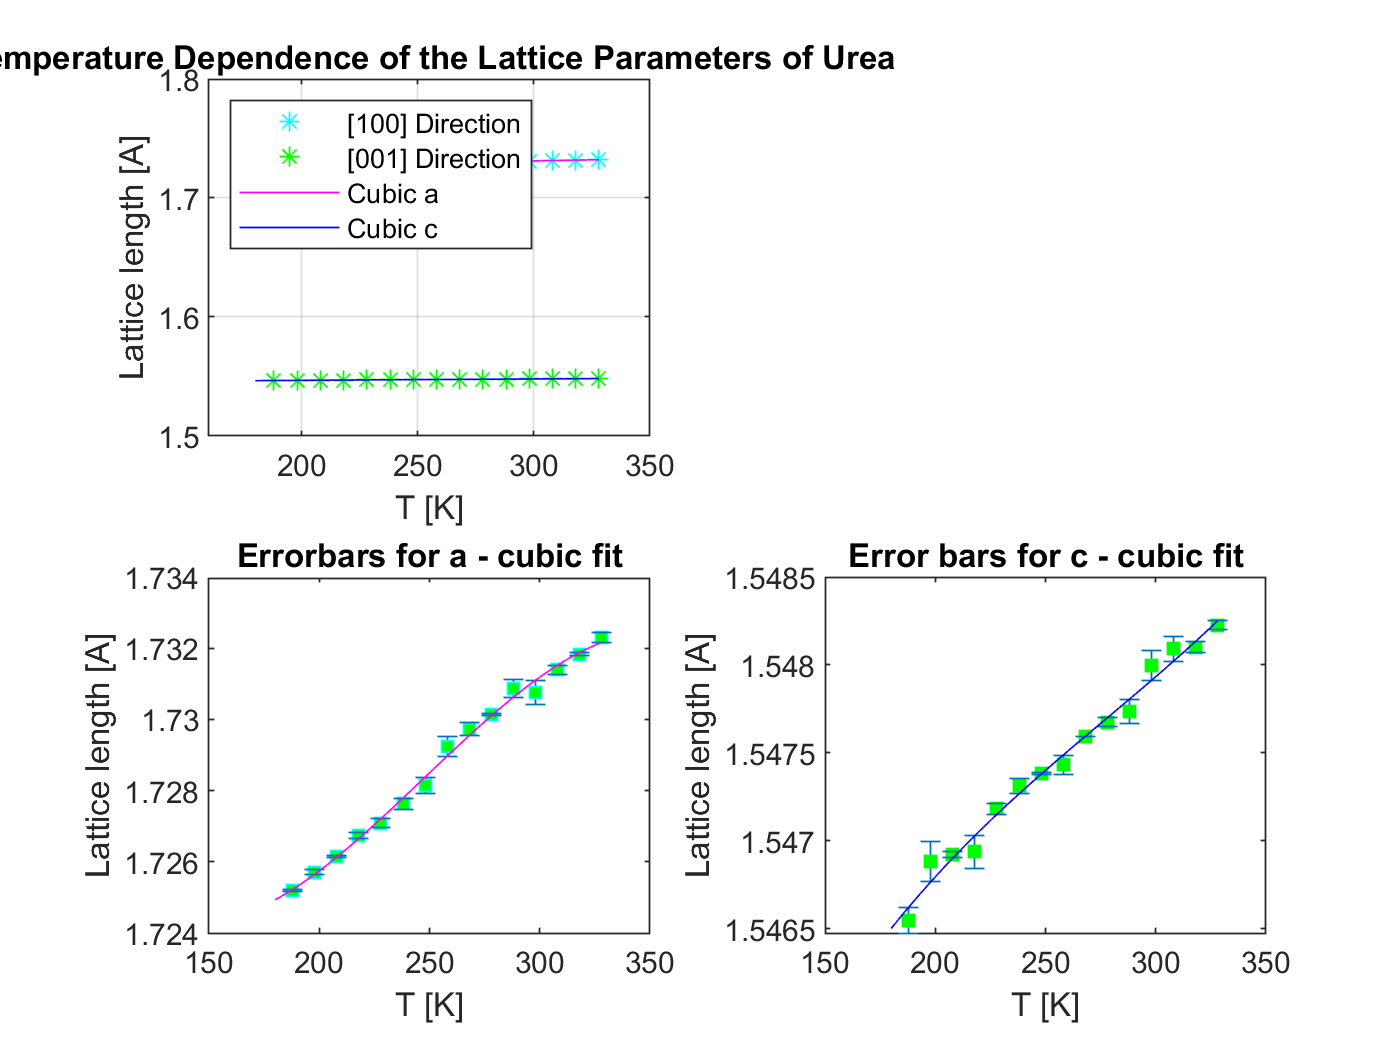

% a/c data
subplot(2,2,1)
plot(x,y,'c*')
hold on
plot(x,y,'g*')
hold on

% polyfitting
% T2 = [180:0.1:328];
% % cubic a
% pfq = polyfit(T,a2,3);
% pvq = polyval(pfq,T2);
% plot(T2,pvq,'m')
% hold on
% % cubic c
% pfcc = polyfit(T,c2,3);
% pvcc = polyval(pfcc,T2);
% plot(T2,pvcc,'b')
x = linspace( 0, pi, 10 );
% make a sine function with 100% random error on it
f = 5* x +17 + 1*rand( 1, length( x ) ); % large random addition, rand( 1, n) generates a vector of n randoms p = polyfit(x ,f , 1 )
% fitting to a line: ie, f = m x + b, p[1]=m and p[2]=b
g = polyval( p , x );
% evaluate the fit ie g(x) = p[1] * x + p[2]
plot( x, f , 'r*' , x , g , 'b-' ); % plot fit and data together title( 'The red stars are data, the blue curve is the fit to the data' ) figure; % creates a place for another plot plot( x, ( f - g ) )
% plot of the residuals

%  axis([160 350 1.50 1.8])
title('Temperature Dependence of the Lattice Parameters of Urea');
xlabel('T [K]');
ylabel('Lattice length [A]');
legend('[100] Direction','[001] Direction','Cubic a','Cubic c','Location','northwest','Orientation','vertical')
hold off
grid on
hold off


% subplot(2,2,4)
% errorbar(T,c2,ccresids,'s','MarkerSize',5,...
%     'MarkerEdgeColor','green','MarkerFaceColor','green')
% hold on
% plot(T2,pvcc,'b')
% % axis([160 350 1.54 1.56])
% xlabel('T [K]');
% ylabel('Lattice length [A]');
% title('Error bars for c - cubic fit')
% hold off

% Statistics
Cubic_a = LinearModel.fit(T,a2,'poly1')

Cubic_a = Linear regression model:
    y ~ 1 + x1 + x1^2 + x1^3

Estimated Coefficients:
                    Estimate          SE         tStat      pValue  
                   ___________    __________    _______    _________

    (Intercept)         1.7414      0.013713     126.99    9.035e-19
    x1             -0.00027636    0.00016404    -1.6847      0.12017
    x1^2             1.354e-06    6.4426e-07     2.1016     0.059435
    x1^3           -1.8222e-09    8.3142e-10    -2.1917     0.050819


Number of observations: 15, Error degrees of freedom: 11
Root Mean Squared Error: 0.000199
R-squared: 0.994,  Adjusted R-Squared: 0.993
F-statistic vs. constant model: 648, p-value = 1.19e-12

Cubic_c = LinearModel.fit(T,c2,'poly1')

Cubic_c = Linear regression model:
    y ~ 1 + x1 + x1^2 + x1^3

Estimated Coefficients:
                    Estimate          SE         tStat        pValue  
                   ___________    __________    ________    __________

    (Intercept)         1.5409     0.0047763      322.62    3.1861e-23
    x1              5.2358e-05    5.7135e-05     0.91639       0.37911
    x1^2           -1.5109e-07     2.244e-07    -0.67332       0.51464
    x1^3            1.8197e-10    2.8959e-10     0.62839       0.54258


Number of observations: 15, Error degrees of freedom: 11
Root Mean Squared Error: 6.93e-05
R-squared: 0.986,  Adjusted R-Squared: 0.982
F-statistic vs. constant model: 250, p-value = 2.11e-10